# Sparity of Dynamical Regression Vector

## Test generated matlab function

addpath("utils\");
Y_Full(zeros(1,7*4))

ans =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -9.8000         0         0         0         0         0         0         0         0         0   -9.8000         0         0         0         0         0         0         0         0         0   -9.8000         0         0   -0.8085         0         0         0         0         0         0   -9.8000         0         0   

## Generate Random Kinematics

Random seed

rng(42);

Dataset size

dataset_size=5e4;

Kinematics dataset

KinematicsData=rand(dataset_size,7*4);
KinematicsData(:,1:7)=2*pi*KinematicsData(:,1:7);
KinematicsData(:,8:14)=2*pi*(KinematicsData(:,8:14)-0.5);
KinematicsData(:,15:21)=2*pi*(KinematicsData(:,8:14)-0.5);
KinematicsData(:,22:28)=2*5*(KinematicsData(:,15:21)-0.5);

## Eliminate $0$-valued columns in $Y_{\text{Full}}$

Generate $Y_{\text{Full}}$ Dataset

DynFullMatData=zeros(dataset_size*7,7*10);
for i=1:dataset_size
    DynFullMatData(7*(i-1)+1:7*i,:)=Y_Full(KinematicsData(i,:));
end
ColumnNorm=zeros(1,7*10);
for i=1:7*10
    ColumnNorm(i)=norm(DynFullMatData(:,i));
end
NotZeroColIndice=ColumnNorm>1e-4;
DynRegMatData=DynFullMatData(:,NotZeroColIndice);
[~,DynRegMatColNum]=size(DynRegMatData);

## Generate Dynamical Regression Vector Dataset

DynRegVecData=zeros(dataset_size,7*DynRegMatColNum);
for i=1:dataset_size
    DynRegVecData(i,:)=reshape(DynRegMatData(7*(i-1)+1:7*i,:),...
        [1,7*DynRegMatColNum]);
end

## Sparity Analysis

Normalize Data

DynRegData_Normalized=zeros(dataset_size,7*DynRegMatColNum);
for i=1:7*DynRegMatColNum
    if DynRegVecData(:,i)==zeros(dataset_size,1)
        DynRegData_Normalized(:,i)=zeros(dataset_size,1);
    else
        DynRegData_Normalized(:,i)=normalize(DynRegVecData(:,i));
    end
end

Obtain Singular Value

s=svd(DynRegData_Normalized);
CompressedRank=sum(s>1e-5)

CompressedRank = 222

Visualization

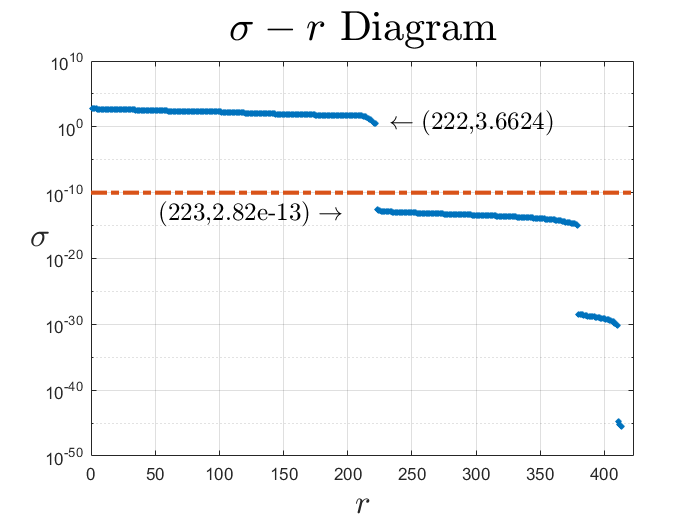

semilogy(s(1:7*DynRegMatColNum),"x","MarkerFaceColor",...
    "blue","MarkerSize",2.5,"LineWidth",3);
hold on
plot([0,length(s)+100],1e-10*[1,1],"LineWidth",2.5,"LineStyle","-.");
text(CompressedRank+10,s(CompressedRank),...
    "$\leftarrow($"+num2str(CompressedRank)+","+...
    num2str(s(CompressedRank))+"$)$","FontSize",...
    15,"Interpreter","latex")
text(CompressedRank-170,s(CompressedRank+1)/5,...
    "$($"+num2str(CompressedRank+1)+","+...
    num2str(s(CompressedRank+1))+"$)\rightarrow$","FontSize",...
    15,"Interpreter","latex")
hold off
grid on
xlabel("$r$","FontSize",20,"Interpreter","latex")
ylabel("$\sigma$","Rotation",0,"FontSize",20,"Interpreter","latex")
title("$\sigma-r$ Diagram","FontSize",25,"Interpreter","latex")
xlim([0,length(s)+10])

## Save Data

writematrix(NotZeroColIndice,"Data\DynParamterUsed.csv")
save("Data\KinematicsData.mat","KinematicsData")
save("Data\DynRegVecData.mat","DynRegVecData")

Remove path

rmpath("utils\")

## Result from `rank()` Function

disp("Rank of unnormalized data with rank() function is "+num2str(rank(DynRegVecData))+".")

Rank of unnormalized data with rank() function is 222.


disp("Rank of normalized data with rank() function is "+num2str(rank(DynRegData_Normalized))+".")

Rank of normalized data with rank() function is 222.
